mydata = load('RSdata.mat')

mydata = struct with fields:
                   rt_tout: [1600×1 double]
           rt_motor_speeds: [1×1 struct]
           rt_optical_flow: [1×1 struct]
    rt_initial_sensor_data: [1×1 struct]
                    rt_a_x: [1×1 struct]
                    rt_a_y: [1×1 struct]
                    rt_a_z: [1×1 struct]
                      rt_p: [1×1 struct]
                      rt_q: [1×1 struct]
                      rt_r: [1×1 struct]
               rt_pressure: [1×1 struct]
           rt_z_ultrasonic: [1×1 struct]



ms = mydata.rt_motor_speeds.signals.values;

u = mydata.rt_optical_flow.signals.values(:,1);
v = mydata.rt_optical_flow.signals.values(:,2);
a_x = mydata.rt_a_x.signals.values;
a_y = mydata.rt_a_y.signals.values;
a_z = mydata.rt_a_z.signals.values;
p = mydata.rt_p.signals.values;
q = mydata.rt_q.signals.values;
r = mydata.rt_r.signals.values;
p_0 = mydata.rt_pressure.signals.values;
z_us = mydata.rt_z_ultrasonic.signals.values;

all_data = [u, v, a_x, a_y, a_z, p, q, r, p_0, z_us];
labels = ["u", "v", "a_x", "a_y", "a_z", "p", "q", "r", "p_0","z_us"];

u_mean = mean(u)

u_mean = single
0.0047

u_cov = cov(u)

u_cov = single
0.0012

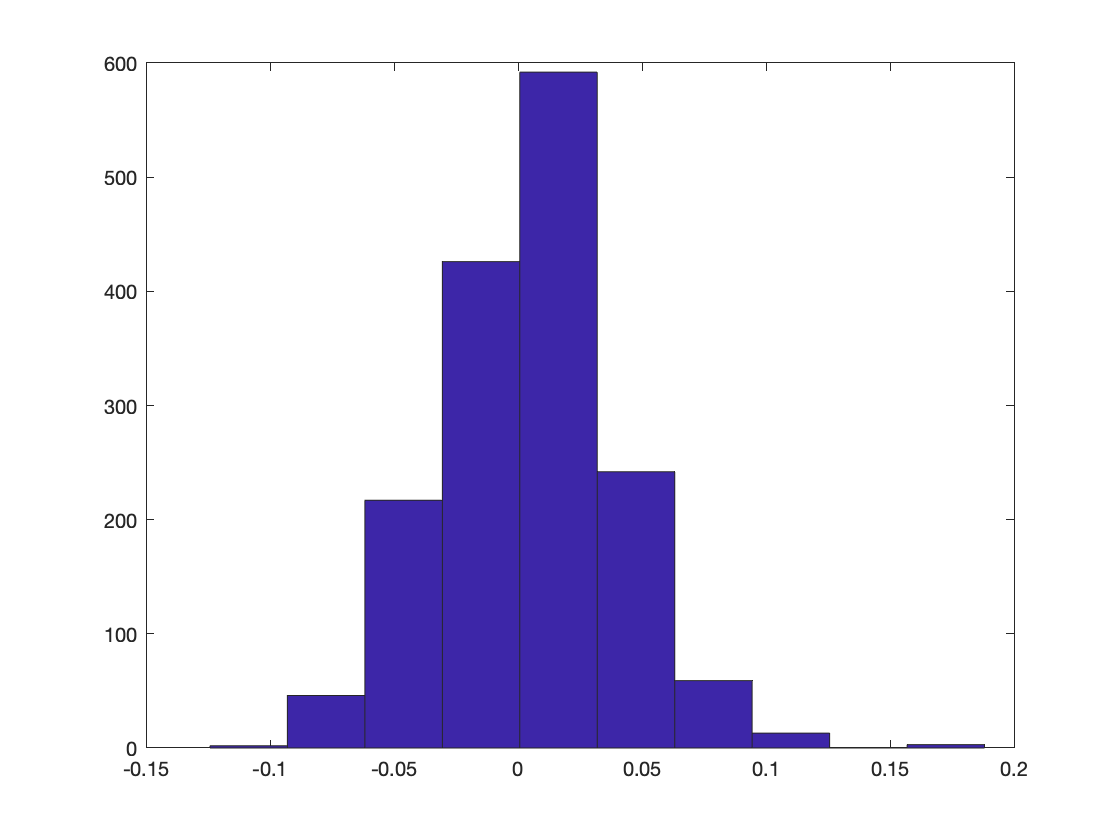

hist(u,10)


v_mean = mean(v)

v_mean = single
0.0025

v_cov = cov(v)

v_cov = single
0.0013

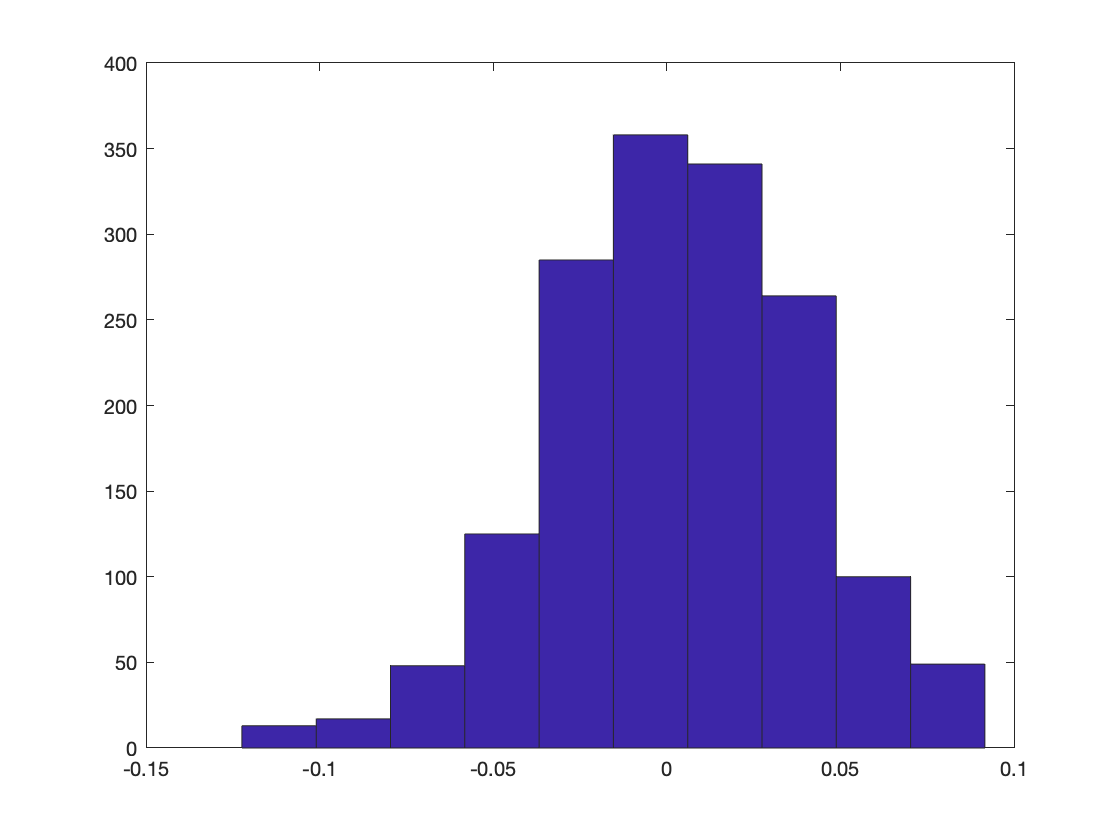

hist(v,10)


a_x_mean = mean(a_x)

a_x_mean = single
-0.4573

a_x_cov = cov(a_x)

a_x_cov = single
0.5712

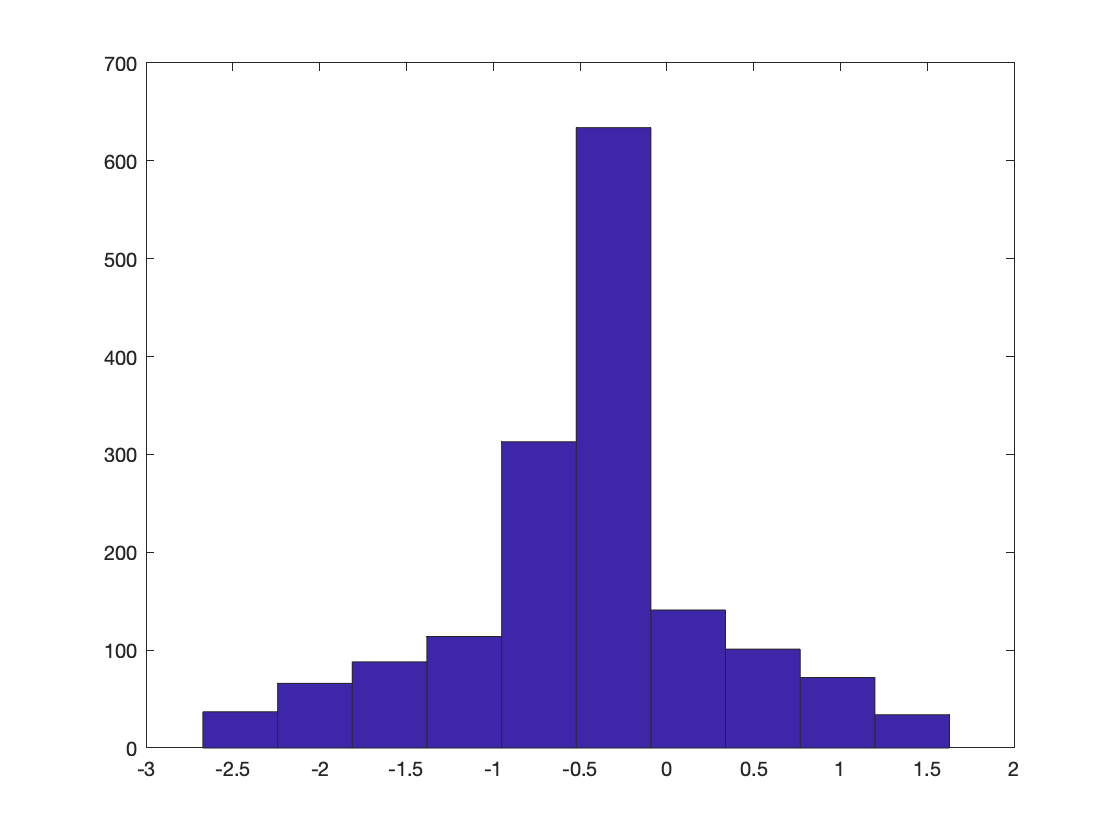

hist(a_x,10)


a_z_mean = mean(a_y)

a_z_mean = single
-0.4013

a_z_cov = cov(a_y)

a_z_cov = single
0.5145

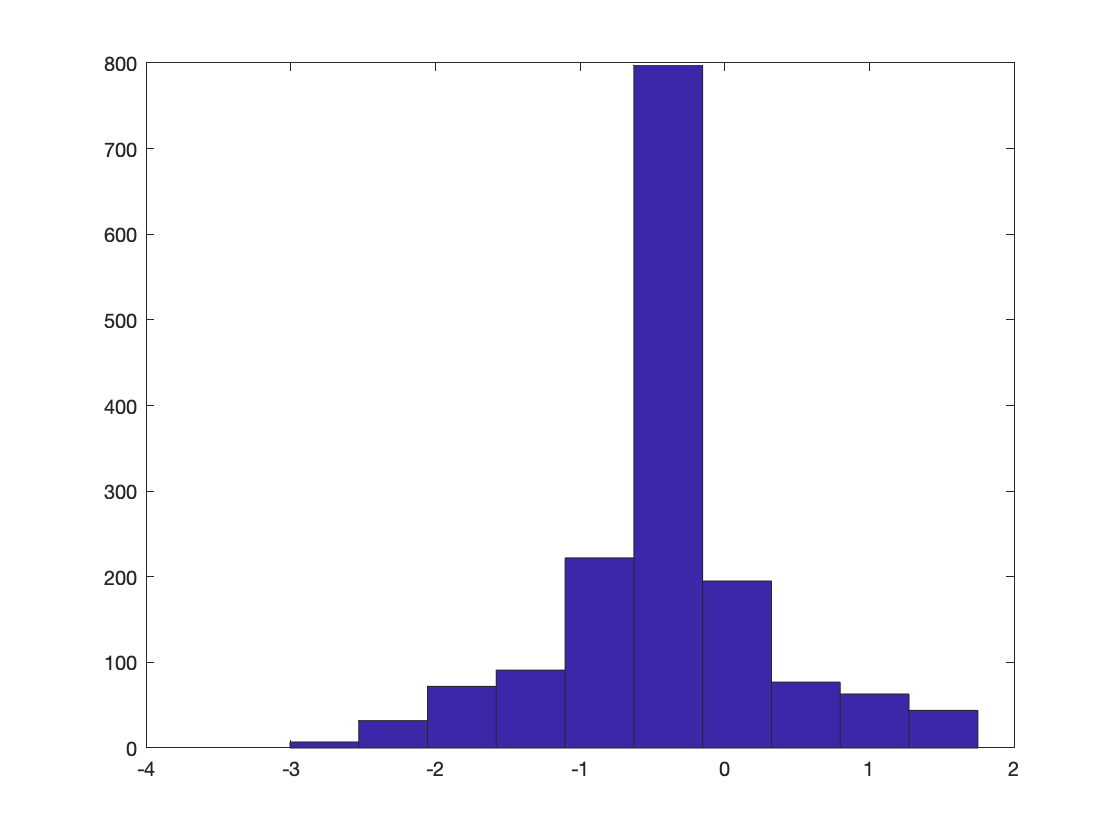

hist(a_y)


a_z_mean = mean(a_z)

a_z_mean = single
-9.1987

a_z_cov = cov(a_z)

a_z_cov = single
0.3128

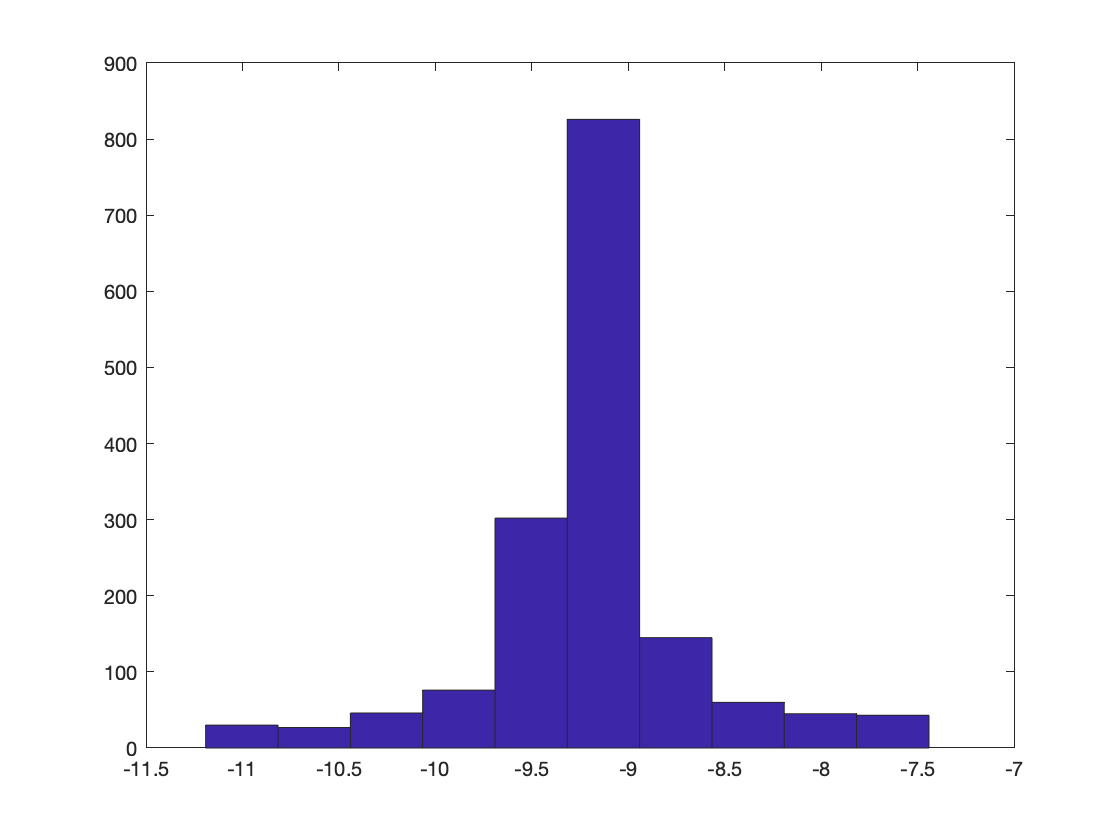

hist(a_z)


p_mean = mean(p)

p_mean = single
-0.0041

p_cov = cov(p)

p_cov = single
0.0014

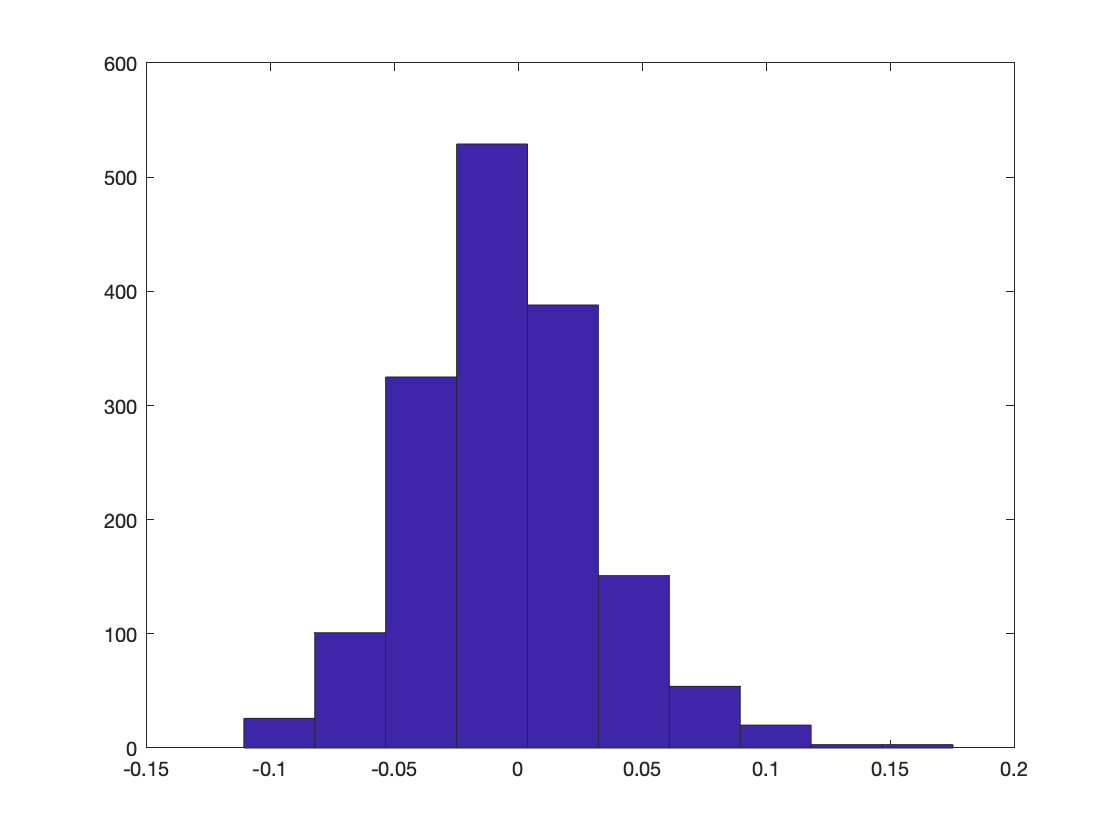

hist(p)


q_mean = mean(q)

q_mean = single
-0.0265

q_cov = cov(q)

q_cov = single
0.0014

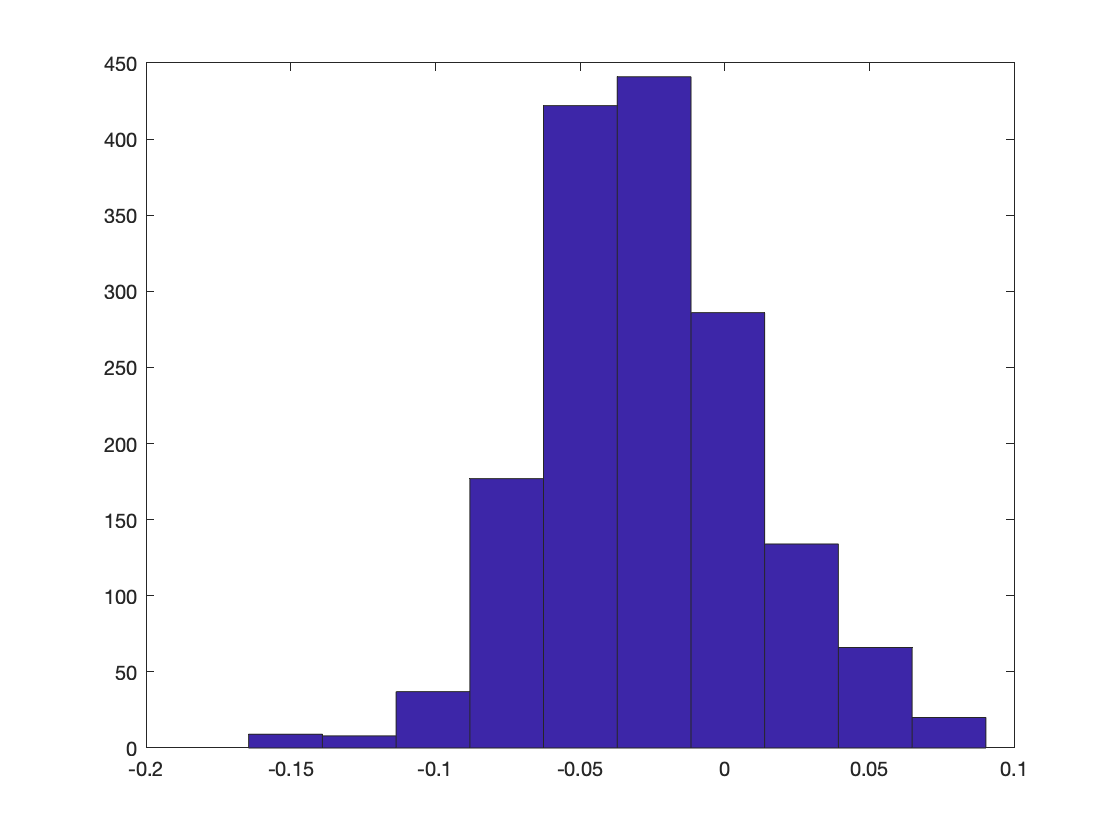

hist(q)


r_mean = mean(r)

r_mean = single
0.0048

r_cov = cov(r)

r_cov = single
0.0021

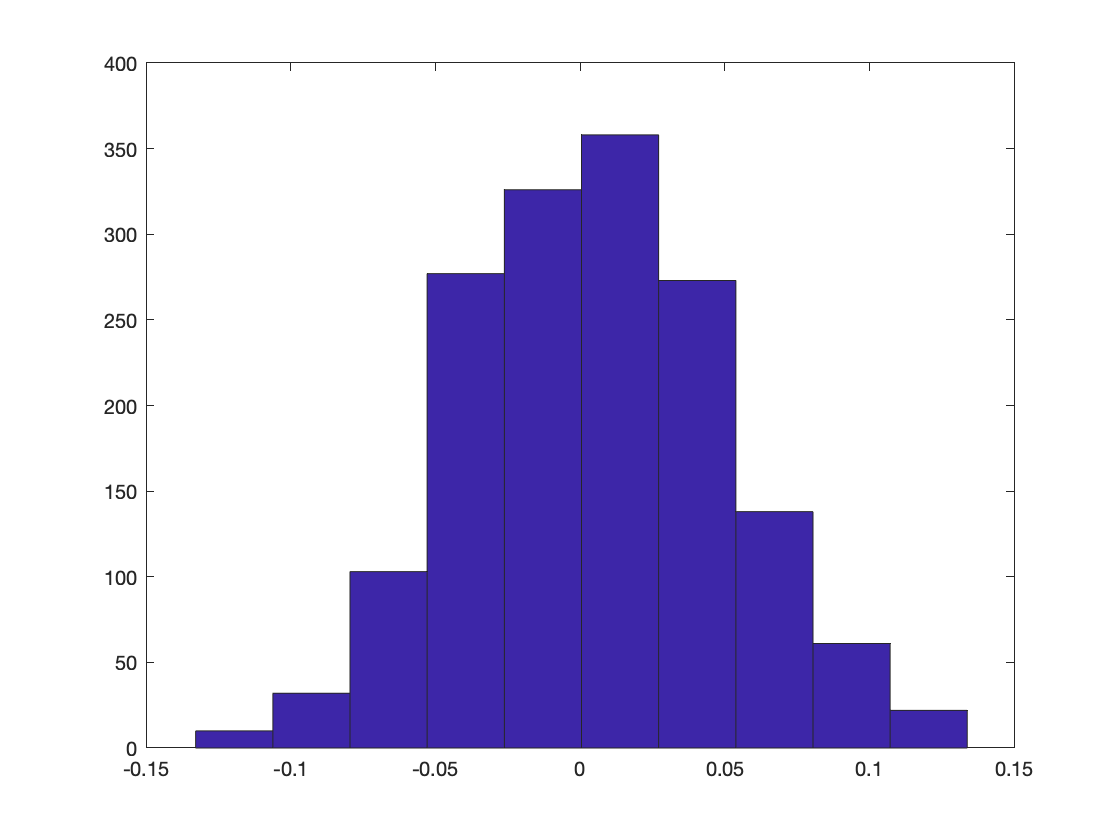

hist(r)


g = 9.8; % acceleration due to gravity m/s^2
M = 0.0289644; % molar mass of air in kg/mol
R = 8.31432; % universal gas constant Nm/mol/k
p0 = 101325 % Pa standard pressure

p0 = 101325


T =288.15;  % Assumed temperature in kelvin
K =-g*M/R/T;
z_hypsometric =@(P) 1/K.*log(P./p0)

z_hypsometric = function_handle with value:
    @(P)1/K.*log(P./p0)


p_0_mean = mean(p_0)

p_0_mean = single
9.9987e+04

difference = z_hypsometric(p_0) - z_hypsometric(p_0_mean)

difference = 1600×1 single column vector
   -0.0770
   -0.0770
    0.1662
    0.1662
    0.1662
    0.1932
    0.1932
    0.1932
    0.1973
    0.1973


p_cov = cov(difference) %p_0

p_cov = single
0.0208

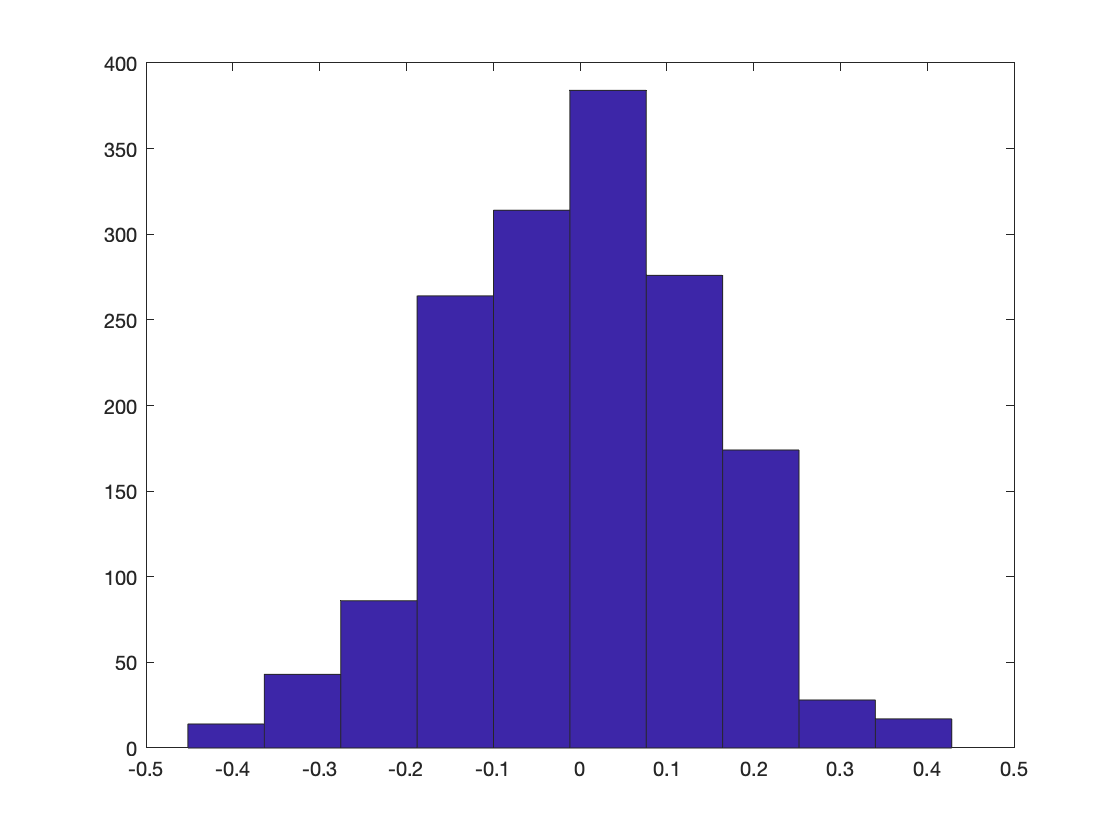

hist(difference)



z_us_mean = mean(z_us)

z_us_mean = single
0.7499

z_us_cov = cov(z_us)

z_us_cov = single
2.4625e-04

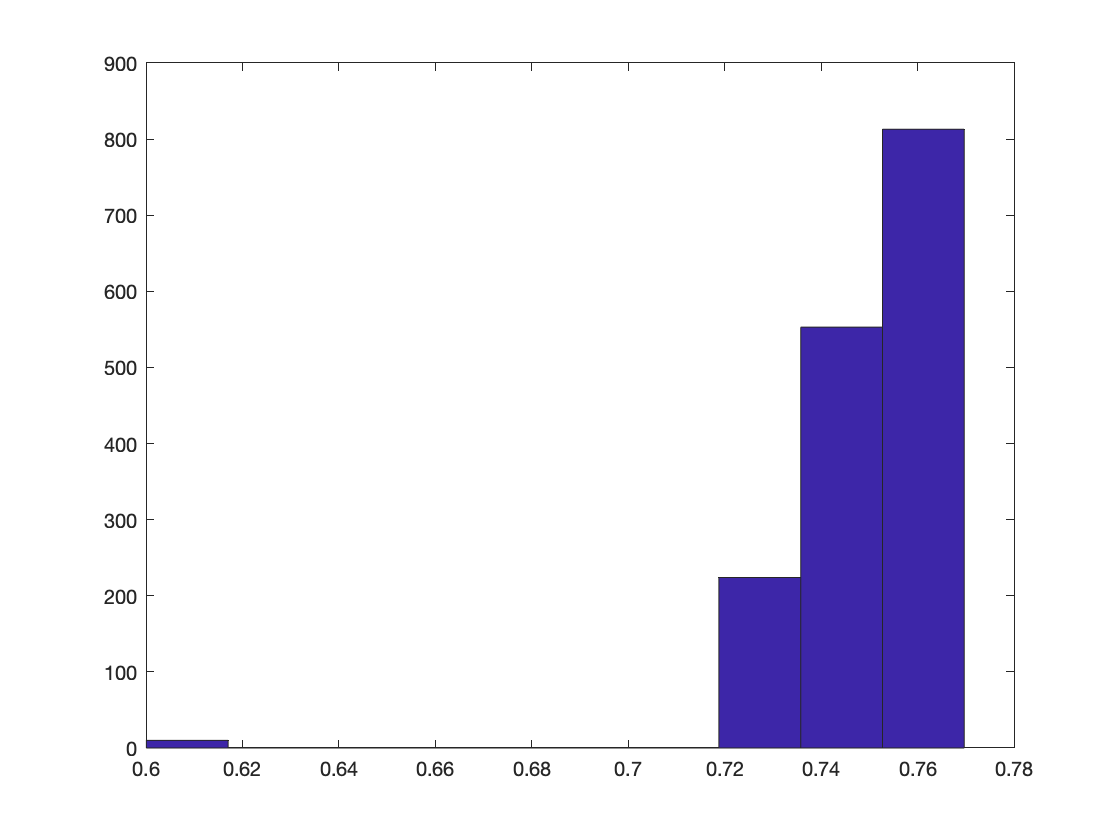

hist(z_us)


for i = 1:10
    for j = 1:10
        correlation = corr(all_data(:,i),all_data(:,j));
        if correlation > 0.3 && (i ~= j)
            fprintf('Correlation between %s and %s is %f \n',labels(i),labels(j),corr(all_data(:,i),all_data(:,j)))
        end
    end
end

Correlation between u and q is 0.360688 
Correlation between a_x and a_z is 0.406689 
Correlation between a_x and p is 0.383370 
Correlation between a_y and q is 0.345313 
Correlation between a_z and a_x is 0.406689 
Correlation between p and a_x is 0.383370 
Correlation between q and u is 0.360688 
Correlation between q and a_y is 0.345313 


corr_matrix = corrcoef(all_data)

corr_matrix = 10×10 single matrix
    1.0000   -0.0324   -0.0016   -0.0451    0.0254    0.2295    0.3607   -0.0528   -0.0089   -0.1990
   -0.0324    1.0000    0.0313   -0.0218    0.0347   -0.3436   -0.2387    0.0607   -0.0057    0.0788
   -0.0016    0.0313    1.0000   -0.8565    0.4067    0.3834   -0.4132   -0.2616    0.0147    0.0498
   -0.0451   -0.0218   -0.8565    1.0000   -0.2858   -0.4276    0.3453    0.1979    0.0237    0.0492
    0.0254    0.0347    0.4067   -0.2858    1.0000    0.1312   -0.3264   -0.7073   -0.0140    0.0065
    0.2295   -0.3436    0.3834   -0.4276    0.1312    1.0000    0.0429   -0.1782    0.0033   -0.0908
    0.3607   -0.2387   -0.4132    0.3453   -0.3264    0.0429    1.0000    0.1160    0.0033   -0.1650
   -0.0528    0.0607   -0.2616    0.1979   -0.7073   -0.1782    0.1160    1.0000    0.0163    0.0522
   -0.0089   -0.0057    0.0147    0.0237   -0.0140    0.0033    0.0033    0.0163    1.0000    0.0950
   -0.1990    0.0788    0.0498    0.0492    0.0065   -0.0

dt = 1/200;

A_e_dis = expm(A_elevator(1:2,1:2).*dt)

A_e_dis =     1.0000   -0.0479
         0    1.0000


B_e_dis = A_elevator(1:2,3).* dt; 
C_e_dis = eye(2)

C_e_dis =      1     0
     0     1


minreal(ss(A_e_dis, B_e_dis, C_e_dis, 0))

ans =
 
  A = 
            x1       x2
   x1        1  -0.0479
   x2        0        1
 
  B = 
             u1
   x1  0.001051
   x2     0.005
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.




Qd = q_cov*dt;

syms a_x a_y a_z h 
theta_estimate = atan(-a_x/sqrt(a_y^2 + a_z^2)) 

$$theta\_estimate = -\mathrm{atan}\left(\frac{a_{x}}{\sqrt{{a_{y}}^{2}+{a_{z}}^{2}}}\right)$$

phi_estimate = atan(a_y/a_z)

$$phi\_estimate = \mathrm{atan}\left(\frac{a_{y}}{a_{z}}\right)$$

Kappa = 1;
% OF_est = K_fudge*z*[u;v];

Unrecognized function or variable 'K_fudge'.

% u_est = OF_est(1)
% v_est = OF_est(2)

